# tilde theta

--- Данные ---

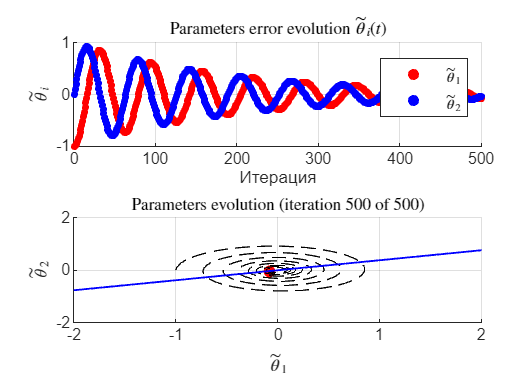

t = 0:0.1:100;               
x = [sin(t)' cos(t)'];       
theta_true = [1; 2];         
y = x * theta_true;          

% --- Гиперпараметры ---
alpha = 1;
num_iters = 500;
m = size(x, 1);

% --- Инициализация ---
theta = [0; 0];
theta_history = zeros(2, num_iters);
J_online_history = zeros(num_iters, 1);
J_full_history = zeros(num_iters, 1); 

% --- Градиентный спуск ---
for iter = 1:num_iters
    % Выбираем i-й пример (зацикливаемся, если iter > m)
    i = mod(iter-1, m) + 1;  % циклический проход по данным
    
    xi = x(i, :)';           % 2×1
    yi = y(i);               % скаляр
    
    % Прогноз и ошибка
    y_pred = xi' * theta;    % скаляр
    error = y_pred - yi;     % скаляр
    
    % Градиент по ОДНОМУ примеру (без деления на m!)
    grad = error * xi;       % 2×1 — ∇_{θ} [0.5 * (xi'θ - yi)^2]
    
    % Обновление
    theta = theta - alpha * grad;
    
    % Сохраняем
    theta_history(:, iter) = theta;
    
    % Ошибки:
    J_online_history(iter) = 0.5 * error^2;                     % локальная ошибка
    J_full_history(iter) = (1/(2*m)) * norm(x * theta - y)^2;   % полная J(θ)
end

% --- Ошибки параметров ---
theta_tilde = theta_history - theta_true;  

% --- Создание макета плиток ---
figure('Position',[300 200 800 600]);
tiledlayout(2,1, 'TileSpacing','compact', 'Padding','compact');

% === Эволюция ошибок параметров ===
ax1=nexttile(1);
scatter(1:num_iters, theta_tilde(1,:), 15, 'r', 'filled'); hold on;
scatter(1:num_iters, theta_tilde(2,:), 15, 'b', 'filled');
xlabel('Итерация');
ylabel('$\tilde{\theta}_i$', Interpreter='Latex');
legend('$\tilde{\theta}_1$', '$\tilde{\theta}_2$', Interpreter='Latex');
title('Parameters error evolution $\tilde{\theta}_i(t)$', Interpreter='Latex');
grid on;

% === Анимация фазовой траектории ===
ax2 = nexttile(2);
hold(ax2,'on');
grid(ax2,'on');
xlabel(ax2,'$\tilde{\theta}_1$','Interpreter','Latex');
ylabel(ax2,'$\tilde{\theta}_2$','Interpreter','Latex');
xlim([-2,2])
ylim([-2,2])

% Элементы анимации
point = plot(ax2, nan, nan, 'ro', 'MarkerFaceColor','r');
traj_line = plot(ax2, nan, nan, 'k--', 'LineWidth', 0.5);
error_line = plot(ax2, nan, nan, 'b-', 'LineWidth', 1); % линия ошибки
title(ax2, sprintf('Parameters evolution (iteration %d of %d)', 1, num_iters), 'Interpreter','Latex');

% --- Анимационный цикл ---
for k = 1:num_iters
    % прямая ошибки на текущей итерации
    xk = x(k,1);
    yk = x(k,2);
    lims = xlim(ax2);
    theta1_line = linspace(lims(1), lims(2), 100);
    theta2_line = -(xk/yk) * theta1_line;

    % обновляем линию ошибки
    set(error_line, 'XData', theta1_line, 'YData', theta2_line);

    % обновляем траекторию
    set(traj_line, 'XData', theta_tilde(1,1:k), 'YData', theta_tilde(2,1:k));
    set(point, 'XData', theta_tilde(1,k), 'YData', theta_tilde(2,k));

    % обновляем заголовок
    title(ax2, sprintf('Parameters evolution (iteration %d of %d)', k, num_iters), 'Interpreter','Latex');

    drawnow;
end

## J

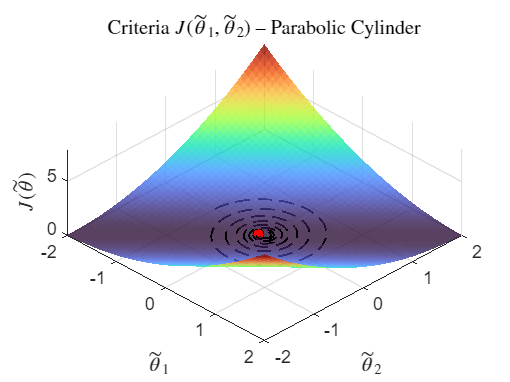

animate_cost_surface(x, y, theta_true, theta_tilde, 'Parabolic Cylinder')


function animate_cost_surface(x, y, theta_true, theta_tilde, title_text)
    traj = theta_tilde';  % Nx2
    N = size(traj,1);

    % --- Сетка для визуализации ---
    theta1_grid = linspace(-2, 2, 50);
    theta2_grid = linspace(-2, 2, 50);
    [T1, T2] = meshgrid(theta1_grid, theta2_grid);

    % --- Подготовка фигуры ---
    figure;
    colormap('turbo');
    xlabel('$\tilde{\theta}_1$', 'Interpreter','latex');
    ylabel('$\tilde{\theta}_2$', 'Interpreter','latex');
    zlabel('$J(\tilde{\theta})$', 'Interpreter','latex');
    title(['Criteria $J(\tilde{\theta}_1, \tilde{\theta}_2)$ -- ', title_text], 'Interpreter','latex');
    grid on;
    view(45, 60);
    hold on;
    zlim([0,8]);

    J_surface = zeros(size(T1));
    surf_handle = surf(T1, T2, J_surface, 'EdgeColor','none', 'FaceAlpha',0.8);
    traj_handle = plot3(traj(1,1), traj(1,2), 0, 'ko', 'MarkerFaceColor','r', 'MarkerSize',6);

    % --- Анимация ---
    for k = 1:5:N
        % Текущие значения x(t) и y(t)
        xk = x(k,:)';     % 2x1
        yk = y(k);
    
        % --- Вычисляем J для всей сетки на этом кадре ---
        for i = 1:numel(T1)
            theta = theta_true + [T1(i); T2(i)];
            y_pred = xk' * theta;        % моментная ошибка
            J_surface(i) = (yk - y_pred)^2;   % квадрат ошибки в момент времени t(k)
        end
    
        % Обновляем поверхность
        set(surf_handle, 'ZData', J_surface);
    
        % Текущая точка траектории
        theta_current = theta_true + traj(k,:)';
        y_pred_current = xk' * theta_current;
        z_traj_current = (yk - y_pred_current)^2;
    
        set(traj_handle, 'XData', traj(k,1), 'YData', traj(k,2), 'ZData', z_traj_current);
    
        drawnow;
    end
    
    % --- Финальная траектория ---
    z_traj = zeros(N,1);
    for k = 1:N
        xk = x(k,:)';
        yk = y(k);
        theta_current = theta_true + traj(k,:)';
        y_pred_current = xk' * theta_current;
        z_traj(k) = (yk - y_pred_current)^2;
    end
    plot3(traj(:,1), traj(:,2), z_traj, 'k--', 'LineWidth',1);
end



## aaa

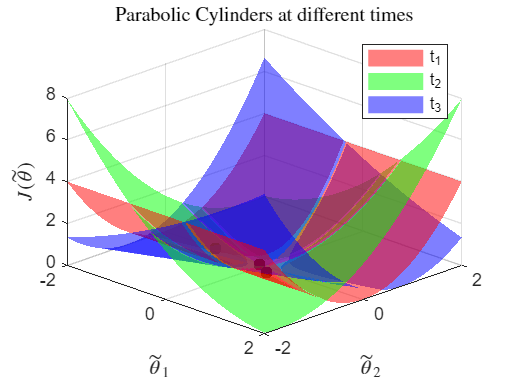

t_vec=[0,45,99];
plot_static_parabolic_cylinders(x, y, theta_true, theta_tilde, t_vec)


function plot_static_parabolic_cylinders(x, y, theta_true, theta_tilde, t_vec)
    N = size(theta_tilde,2);

    % --- Сетка для theta ---
    theta1_grid = linspace(-2, 2, 50);
    theta2_grid = linspace(-2, 2, 50);
    [T1, T2] = meshgrid(theta1_grid, theta2_grid);

    % --- Переводим моменты времени в индексы ---
    t_max = max(t_vec);
    t_indices = round((t_vec/t_max) * (N-1)) + 1;

    % --- Подготовка фигуры ---
    figure;
    hold on;
    colormap turbo;
    xlabel('$\tilde{\theta}_1$', 'Interpreter','latex');
    ylabel('$\tilde{\theta}_2$', 'Interpreter','latex');
    zlabel('$J(\tilde{\theta})$', 'Interpreter','latex');
    title('Parabolic Cylinders at different times', 'Interpreter','latex');
    grid on;
    view(45, 30);
    zlim([0,8]);

    colors = {'r','g','b'};

    % --- Строим параболические цилиндры ---
    for k = 1:length(t_indices)
        idx = t_indices(k);
        xk = x(idx,:)';
        yk = y(idx);

        J_surface = zeros(size(T1));
        for i = 1:numel(T1)
            theta = theta_true + [T1(i); T2(i)];
            y_pred = xk' * theta;
            J_surface(i) = (yk - y_pred)^2;
        end

        surf(T1, T2, J_surface, 'EdgeColor','none', 'FaceAlpha',0.5, 'FaceColor', colors{k});
    end

    % --- Точки текущих ошибок параметров ---
    for k = 1:length(t_indices)
        idx = t_indices(k);
        xk = x(idx,:)';
        yk = y(idx);
        theta_current = theta_true + theta_tilde(:,idx);
        y_pred_current = xk' * theta_current;
        z_val = (yk - y_pred_current)^2;
        plot3(theta_tilde(1,idx), theta_tilde(2,idx), z_val, 'ko', 'MarkerFaceColor','k', 'MarkerSize',6);
    end

    legend('t_1','t_2','t_3','Location','northeast');
end